clear all
clc
addpath('utils/')
addpath('Realization/')

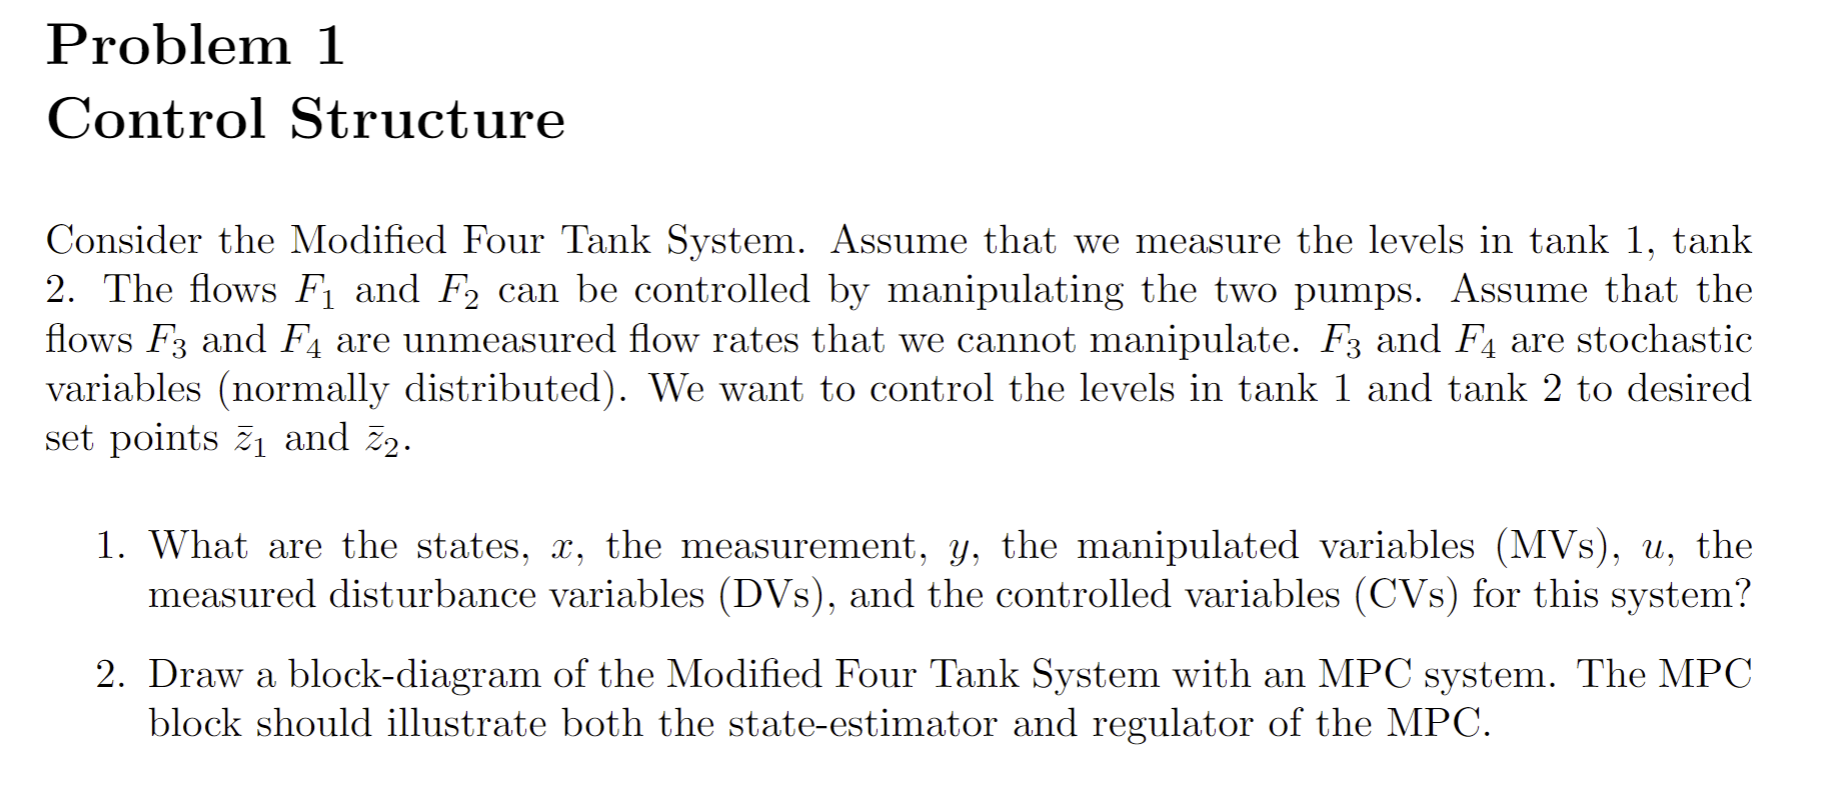

% 1
% State variables are m1, m2, m3 and m4
% Measurement, y: h1, h2, h3, h4
% MV, u, is flow rates from pump 1 and 2> F1, F2
% DV, is disturbance, F3 and F4
% CV, is h1 and h2



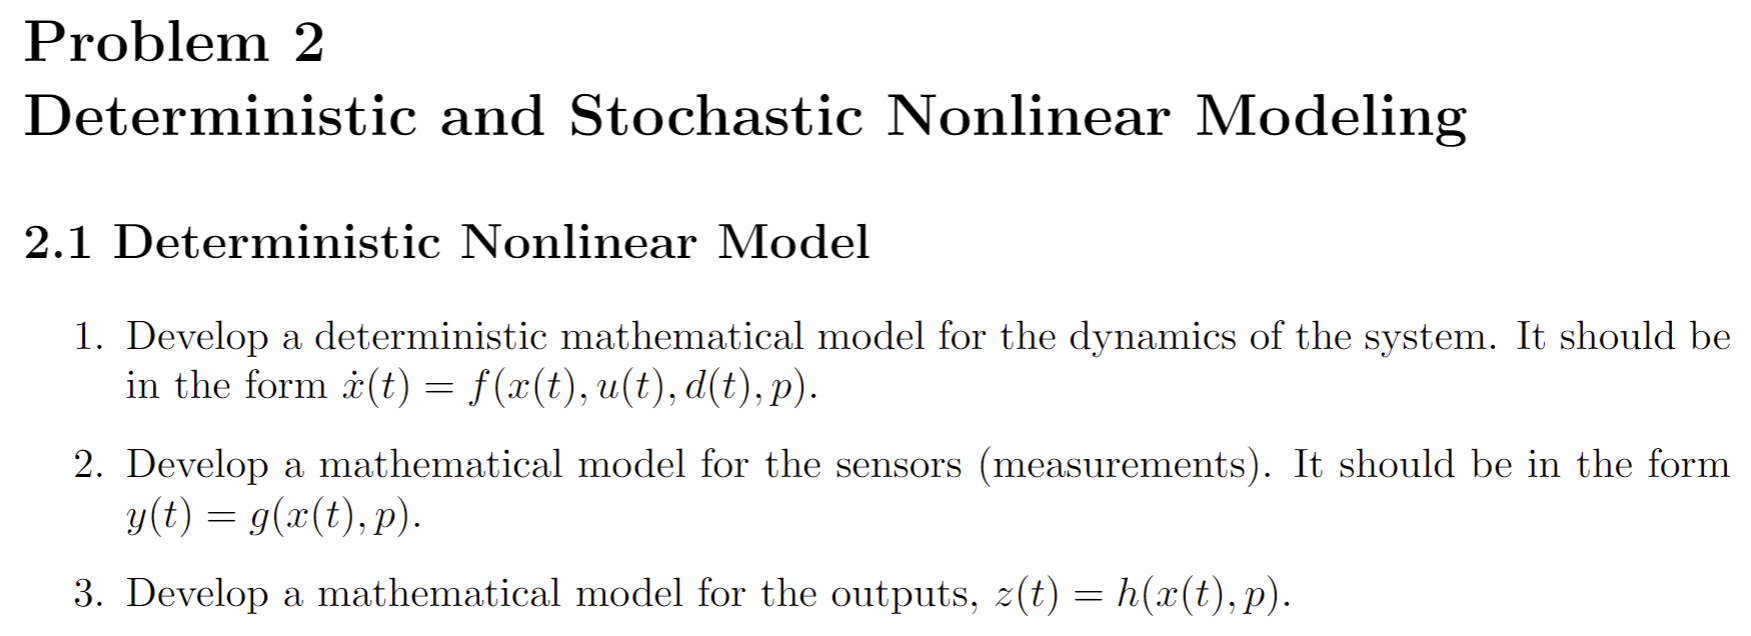

fprintf("Deterministic Nonlinear Model")

Deterministic Nonlinear Model

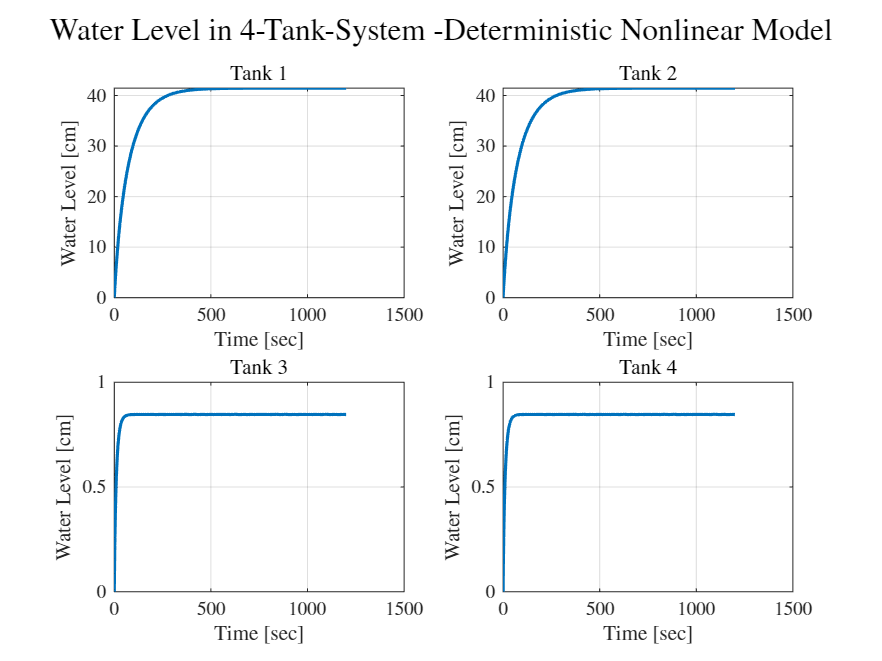

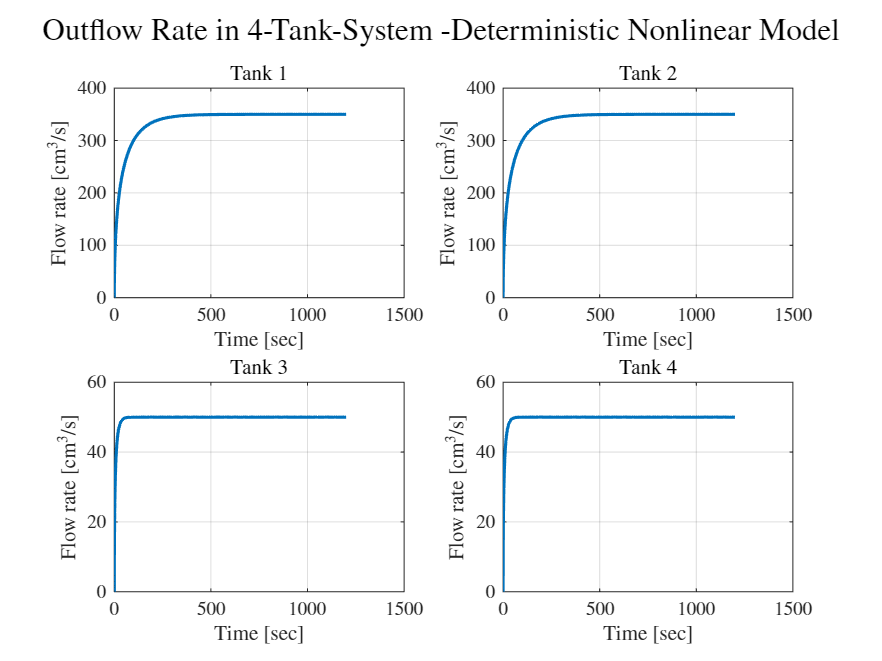

% get parameters
p = param();

%Flow input
U = 300;
%Disturbance
D = 50;

% flow rate steady state
F = [U U D D];

% simulate
[t y q] = sim_dem(F, p);


plotting(t, y, q, "Deterministic Nonlinear Model")

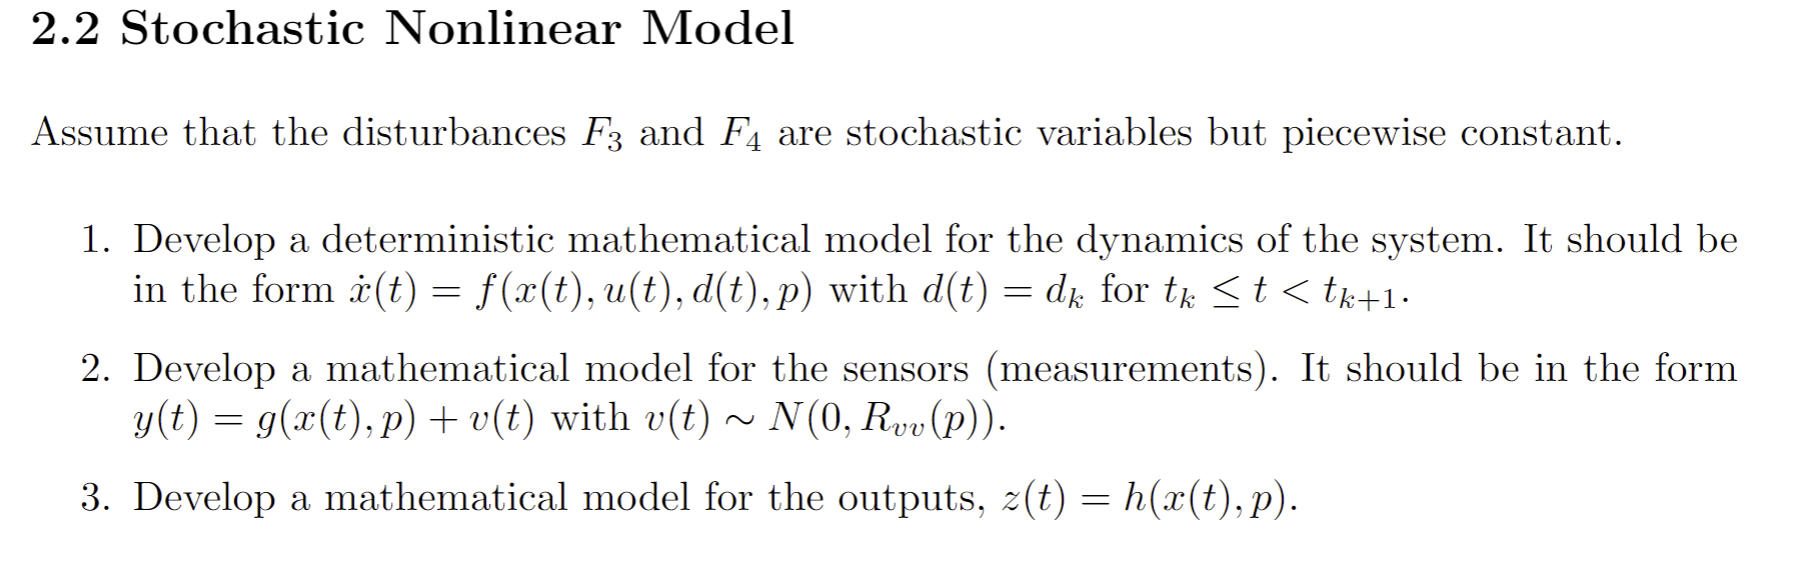

fprintf("Stochastic Nonlinear Model with measurement nosie")

Stochastic Nonlinear Model with measurement nosie

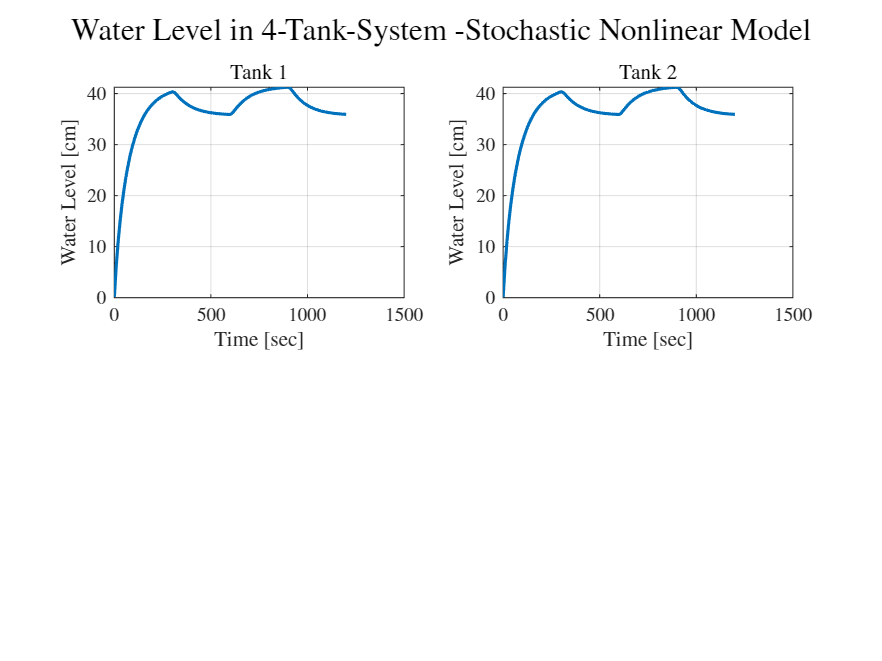

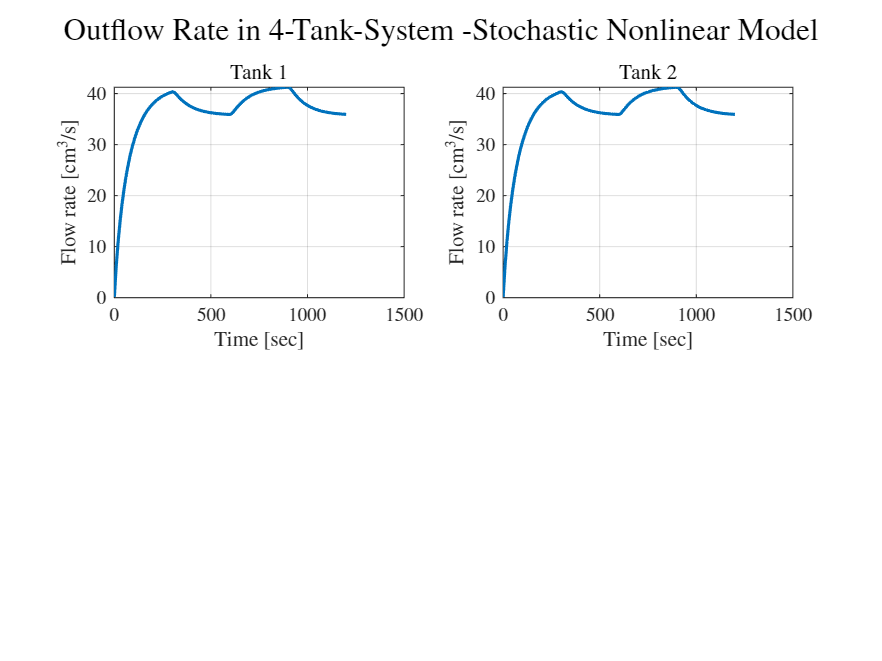


t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

F1 = 300;
F2 = 300;
u = [repmat(F1,1,N); repmat(F2,1,N)];   % control 

% Initialize disturbances for F3 and F4 as square waves
d = zeros(2, N);  % Pre-allocate a 2xN matrix

% Define period and amplitude of the square waves
period = 30;       % Length of one period of the square wave
amplitude = 25;     % Amplitude of the square wave


for i = 1:period:N
    if mod(i, 2*period) < period
        d(:, i:min(i+period-1, N)) = 2*amplitude;
    else
        d(:, i:min(i+period-1, N)) = amplitude;
    end
end

r = [13, 10, 4, 4];
parameters = param();

P = eye(1);
Pq = chol(P,'lower');

% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);


z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];

for k = 1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    z(:,k) = FourTankSystemOutput(x(:,k),parameters);
    % Output function
    disturbance_without_noise_1 = d(:,k); % +w(:,k);
    [Tk,Xk] = ode45(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k),disturbance_without_noise_1,parameters);
    x(:,k+1) = Xk(end,:)';
    % T = [T; Tk];
    X = [X; Xk];
end

k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function


[nA nX] = size(Xk);
g = 981; %[cm/s2] The acceleration of gravity
a = 1.2272; 
nT = length(y(1,:));
Qout = zeros(nX,nT);


for i=1:nT
    Qout(:,i) = a.*sqrt(2*g.*y(:,i)); 
end
plotting(t, z', z', "Stochastic Nonlinear Model");

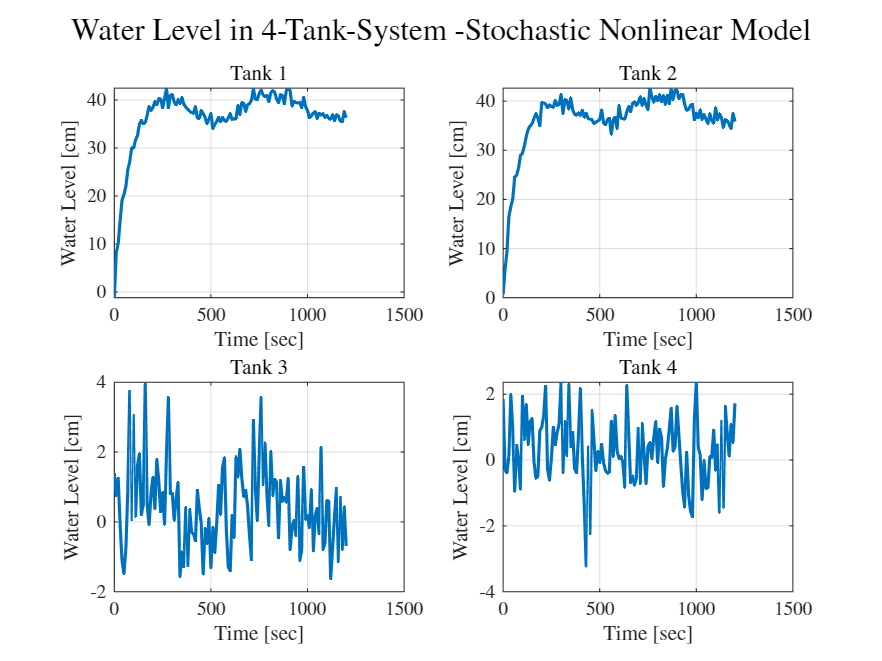

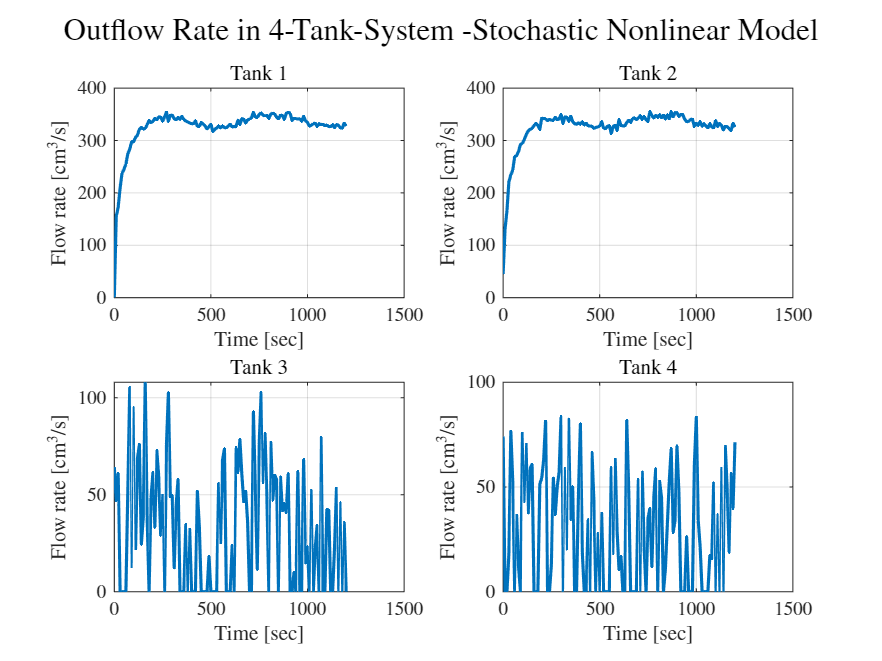

plotting(t, y', Qout', "Stochastic Nonlinear Model");

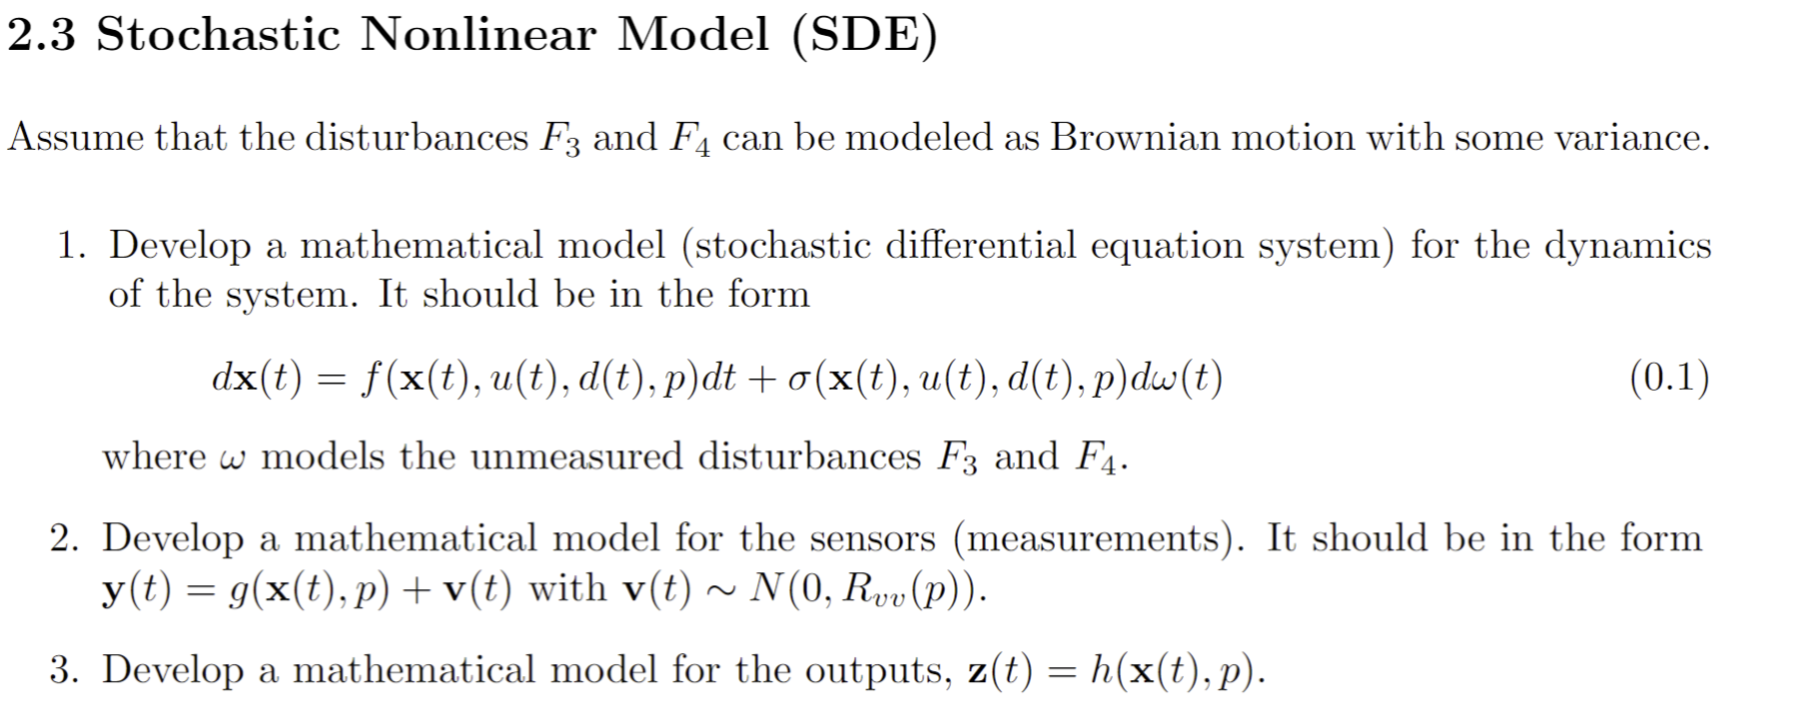

fprintf("SDE")

SDE

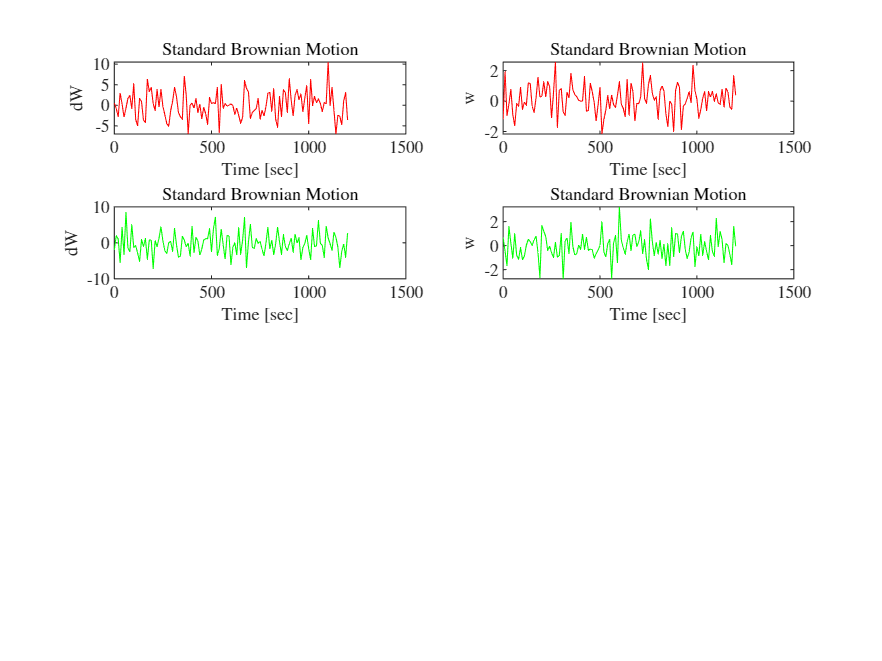

t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = [t0:Ts:tfin];     % time vector
N = length(t);

sz = 4;
su = 2;

% Realization of Ns Standard Brownian Motions
Ns = 2;            % Number of realizations
seed = 100;         % Seed for reproducibility
rng(seed);
dV = sqrt(Ts)*randn(Ns,N); 
d_s = cumsum(dV,2);

figure()
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,1)
plot(t,dV(1, :), 'color', 'r')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,2)
plot(t,v(1,:), 'color', 'r')
xlabel('Time [sec]','interpreter','latex')
ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,3)
plot(t,dV(2, :), 'color', 'g')
xlabel('Time [sec]','interpreter','latex')
ylabel('dW','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')
subplot(4,2,4)
plot(t,v(2, :), 'color', 'g')
xlabel('Time [sec]','interpreter','latex')
ylabel('w','interpreter','latex')
title('Standard Brownian Motion','interpreter','latex')

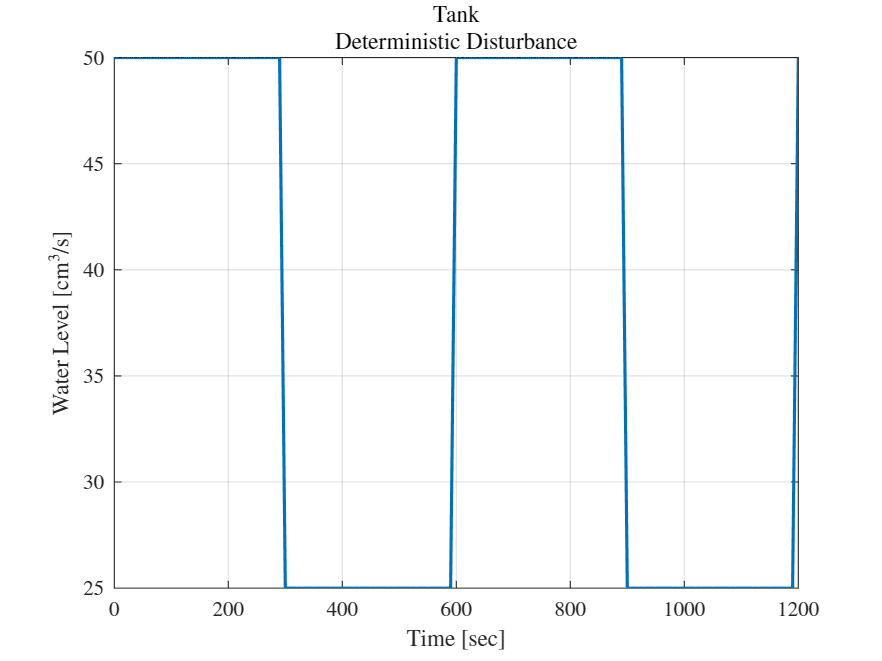



F1 = 300;
F2 = 300;
u = [repmat(F1,1,N); repmat(F2,1,N)];   % control 

% Measurement Noise setup
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);


nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);

% Process noise
Q = [2 1; 1 10];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);




z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
step_size = 0.01;
x(:,1) = [0;0;0;0];


for i = 1:period:N
    if mod(i, 2*period) < period
        d(:, i:min(i+period-1, N)) = 2*amplitude;
    else
        d(:, i:min(i+period-1, N)) = amplitude;
    end
end

d_plot = d(1, :);

figure()
plot(t, d_plot, 'LineWidth', 1.5);
title(['Tank ', "Deterministic Disturbance"], 'interpreter', 'latex');
xlabel('Time [sec]', 'interpreter', 'latex');
ylabel('Water Level [cm$^3$/s]', 'interpreter', 'latex');
grid on; % Add grid

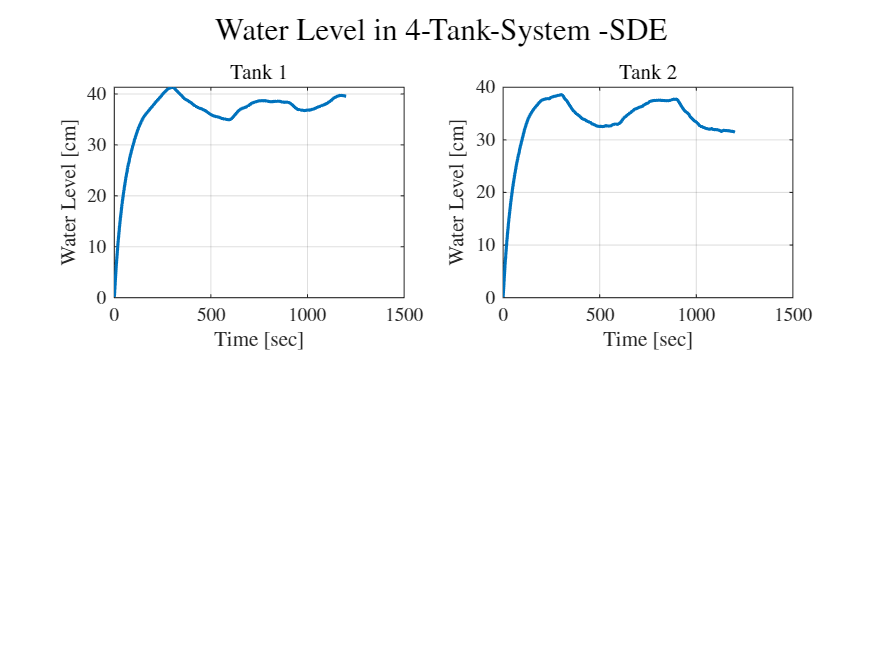

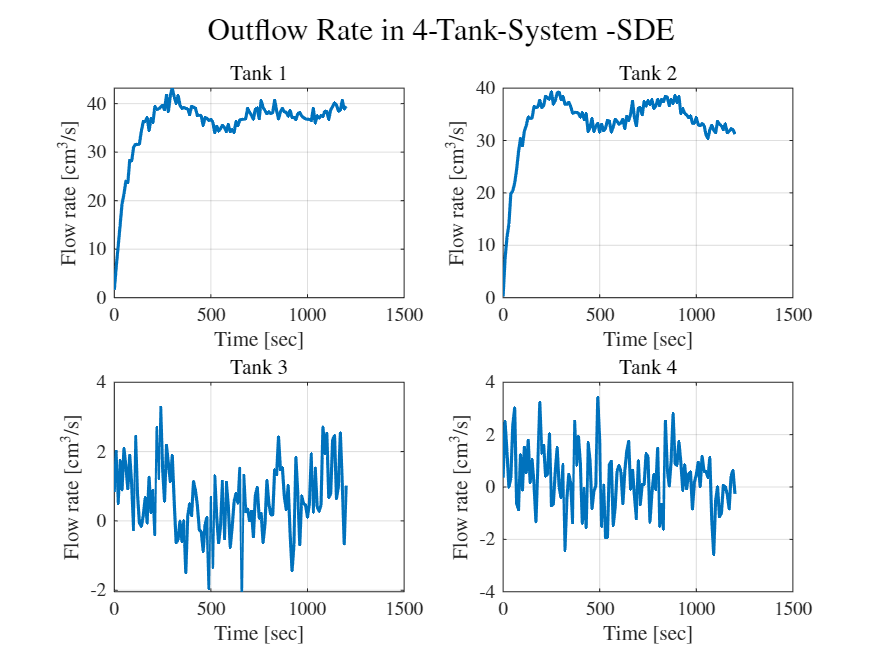



for k = 1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),parameters)+v(:,k); % Sensor function WITH noise 
    z(:,k) = FourTankSystemOutput(x(:,k),parameters);
    % Output function
    disturbance = d(:,k) + d_s(:,k);
    [Tk,Xk] = ode45(@ModifiedFourTankSystem,[t(k):step_size:t(k+1)],x(:,k),[], ...
        u(:,k)+ w(:,k),disturbance,parameters);
    x(:,k+1) = Xk(end,:)';
    % T = [T; Tk];
    X = [X; Xk];
end


k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters) + v(:,k); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function


plotting(t, z', y', "SDE");

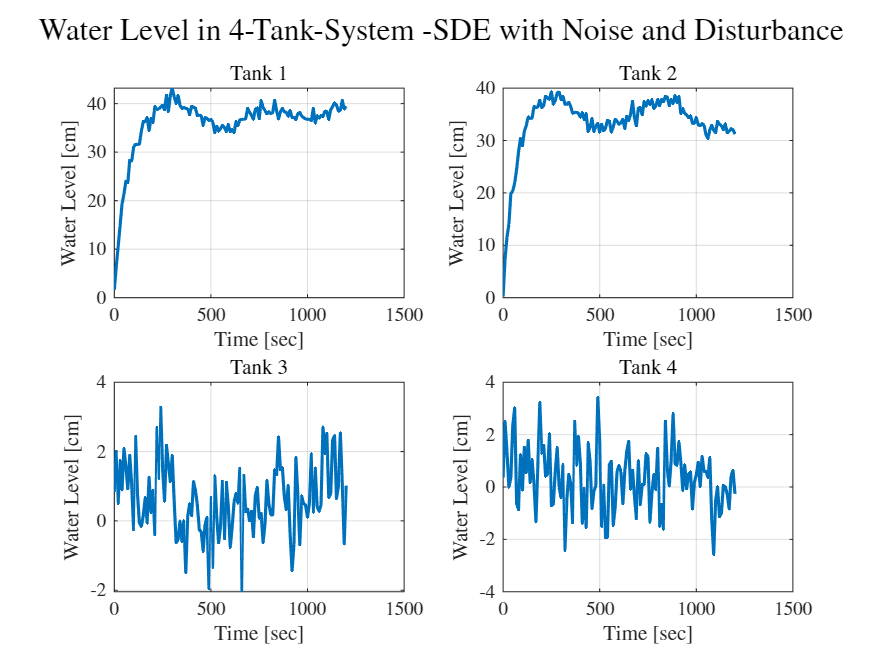

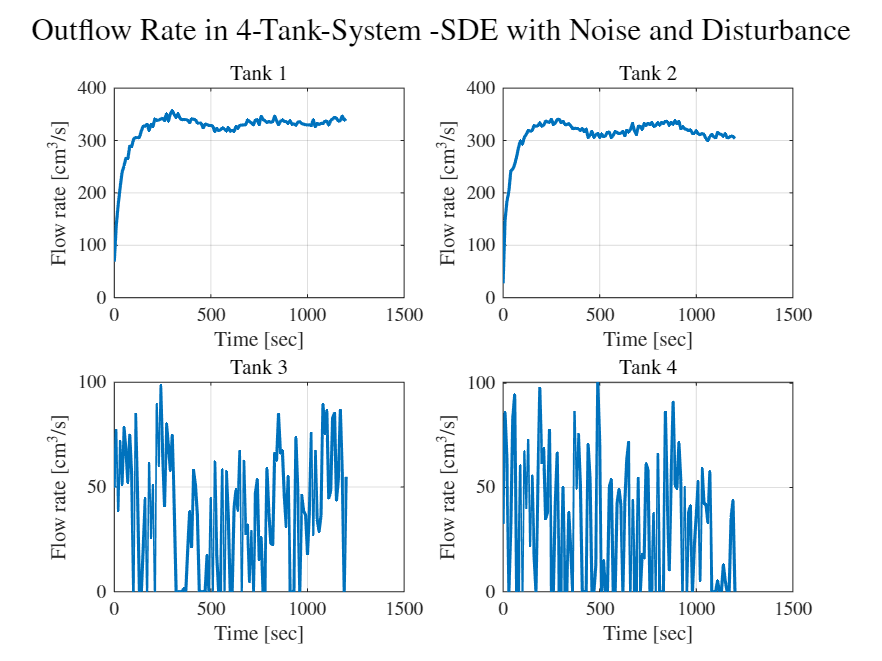



for i=1:nT
    Qout(:,i) = a.*sqrt(2*g.*y(:,i)); 
end
plotting(t, y', Qout', "SDE with Noise and Disturbance");

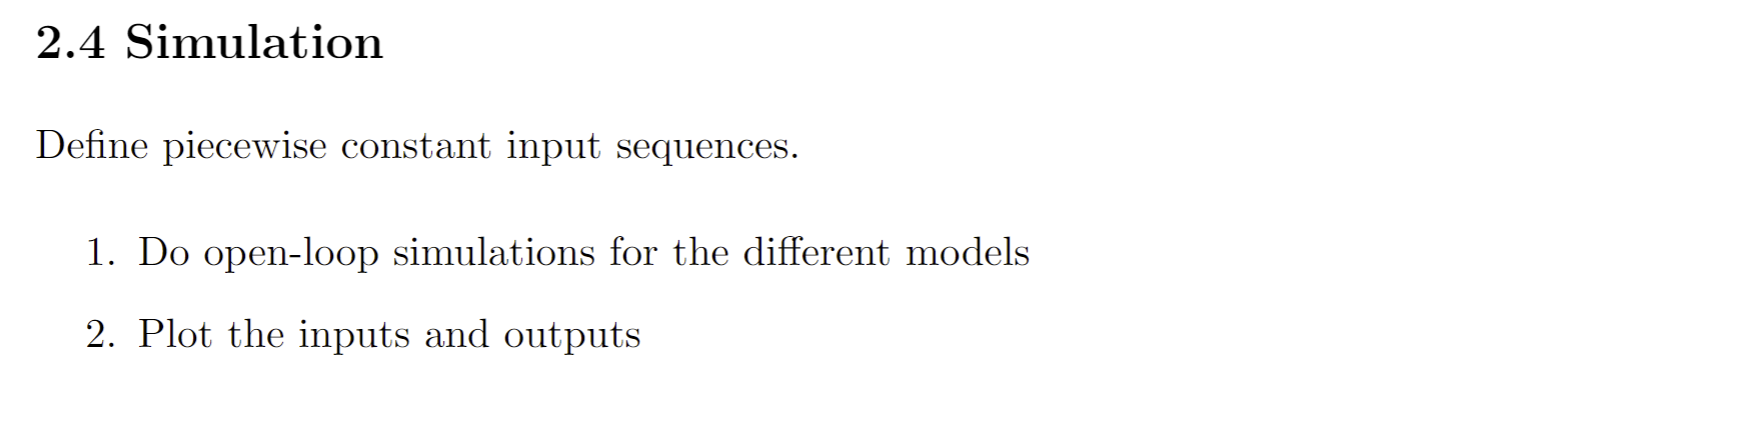

fprintf("SDE with Euler-Maruyama Method\n")

SDE with Euler-Maruyama Method


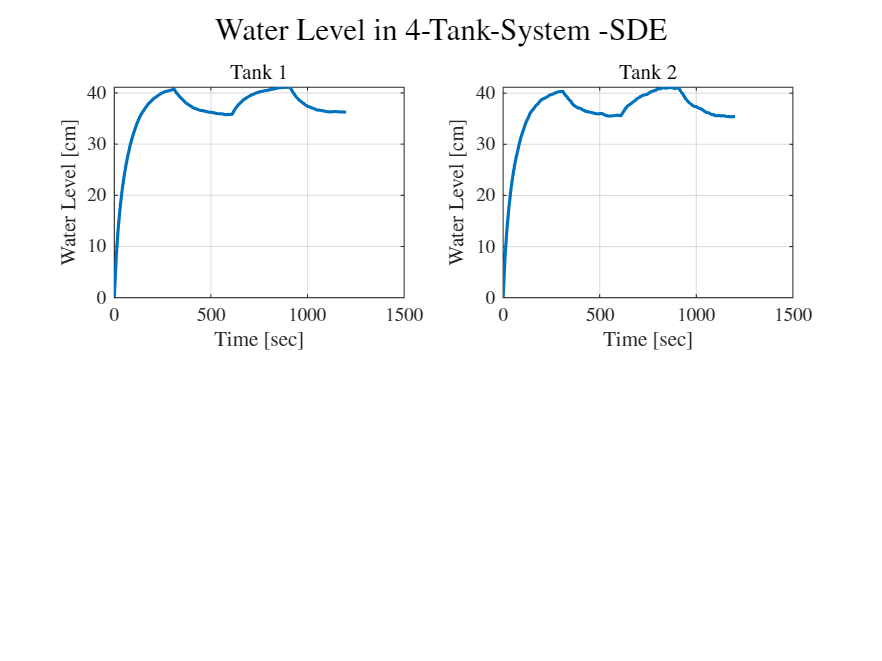

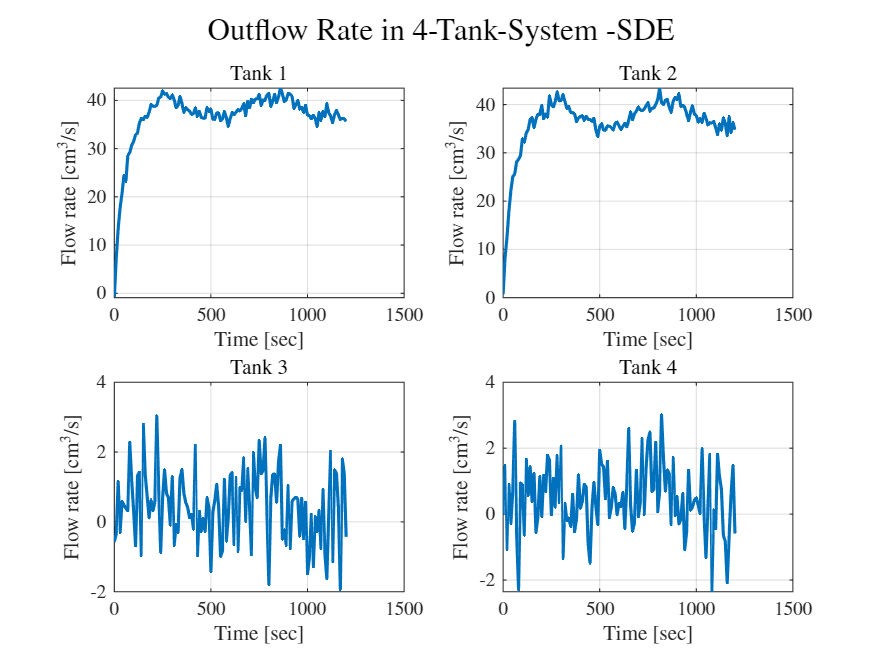


t0 = 0.0;
tfin = 20*60;
Ts = 10;
t = t0:Ts:tfin; % time vector
N = length(t);

% System parameters
F1 = 300; % control input for F1
F2 = 300; % control input for F2
u = [repmat(F1,1,N); repmat(F2,1,N)]; % control inputs matrix

% Initialize parameters
parameters = param(); % Define your system parameters here

% Initialize disturbances for F3 and F4 as square waves
d = zeros(2, N); % Pre-allocate a 2xN matrix

% Define period and amplitude of the square waves
period = 30; % Length of one period of the square wave
amplitude = 25; % Amplitude of the square wave

% Generate square wave pattern for deterministic disturbance
for i = 1:period:N
    if mod(i, 2*period) < period
        d(:, i:min(i+period-1, N)) = 2*amplitude;
    else
        d(:, i:min(i+period-1, N)) = amplitude;
    end
end

% Generate stochastic disturbance
seed = 100; % Seed for reproducibility
rng(seed); % Set the seed
dV = sqrt(Ts)*randn(Ns,N); 
d_s = cumsum(dV,2);


Q = [2 1; 1 10]; % Process noise covariance matrix
Lq = chol(Q,'lower');
w = Lq * randn(2, N); % Generation of the stochastic disturbance

% Initialize state, output, and measurement matrices
nx = 4; % Number of states
ny = 4; % Number of measurements
nz = 2; % Number of outputs
x = zeros(nx, N); % State matrix
y = zeros(ny, N); % Measurement matrix
z = zeros(nz, N); % Output matrix

% Measurement noise setup
R = eye(4);
Lr = chol(R,'lower');
v = Lr * randn(4, N); % Measurement noise realization

d_stoc = zeros(4, 121);    % Create a 4x121 matrix of zeros
d_stoc(3:4,:) = d_s;


% Euler-Maruyama method for SDE approximation
for k = 1:N-1
    % Calculate the deterministic part using the ModifiedFourTankSystem function
    xdot = ModifiedFourTankSystem(t(k), x(:, k), u(:, k)+w(:,k), d(:, k), parameters);
    
    % Euler-Maruyama update for the state
    x(:, k+1) = x(:, k) + xdot * Ts + d_stoc(:, k);
    
    % Update measurements and outputs with noise
    y(:, k) = FourTankSystemSensor(x(:, k), parameters) + v(:, k); % Sensor function WITH noise 
    z(:, k) = FourTankSystemOutput(x(:, k), parameters); % Output function
end

k = N;
y(:,k) = FourTankSystemSensor(x(:,k),parameters) + v(:,k); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),parameters);        % Output function


plotting(t, z', y', "SDE");

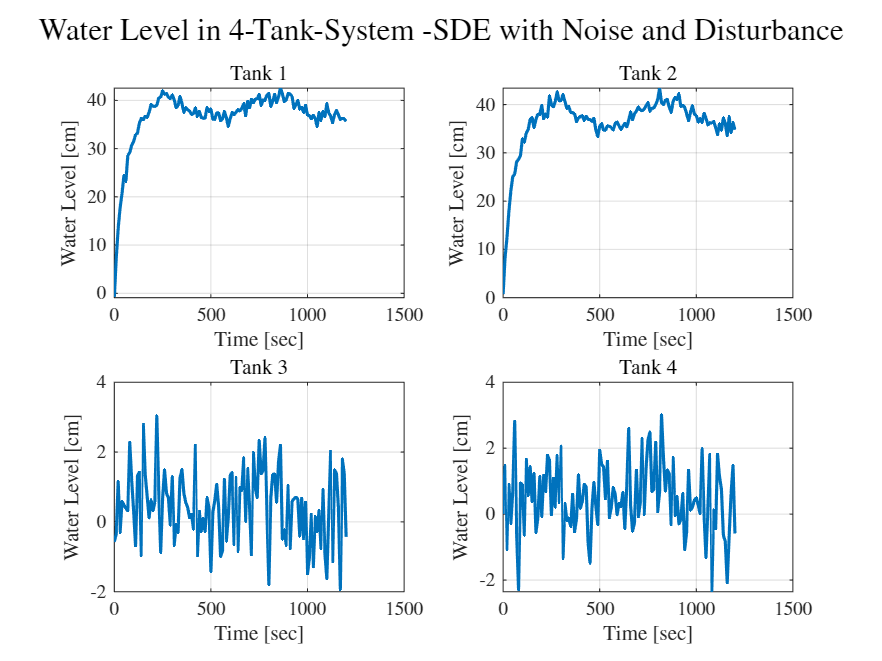

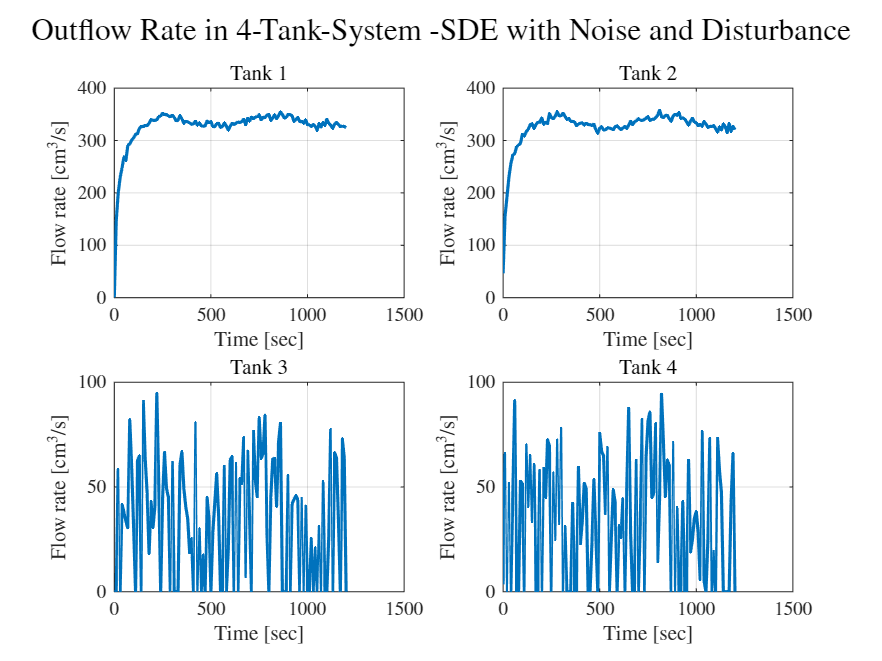


for i=1:nT
    Qout(:,i) = a.*sqrt(2*g.*y(:,i)); 
end
plotting(t, y', Qout', "SDE with Noise and Disturbance");